# Plain GNN - Node classification - for optimization design of RC beams

This example shows how to classify nodes to estimate optimum amounts of number of rebar layers for beams' cross-sections.

clear all

doTraining = false;

## Load Data

Give the path of the folder where the data is stored.

Adjust it to your own path.

A=importdata('Datasets/Data_1LOT_HK_Nb_Db_Simple_4000.xlsx');

Change the variable subsize when not all data is required

DR=A.data;
n=size(DR,1);
subsize=4000;
idxSubData=ceil(rand(subsize,1)*n);
DR=DR(idxSubData,:);
numObservations=length(DR(:,1));
numObservations

numObservations = 4000

Input features

X = [DR(:,1:7)];

## Prepare Data for Training

Extract and concatenate the node features.


Y = [DR(:,10:18)];

Y1 = [];
for i=1:numObservations
    if sum(Y(i,:))~=0
        nlay1=sum(Y(i,1:3)>0);
        nlay2=sum(Y(i,4:6)>0);
        nlay3=sum(Y(i,7:9)>0);
        
        Y1=[Y1;[nlay1,nlay2,nlay3]];
    end
end

numObservations=length(Y1(:,1));

YN1=Y1(:,1); % Node 1: Left
YN2=Y1(:,2); % Node 2: Middle
YN3=Y1(:,3); % Node 3: Right

## **GNN connectivity**

elements=[2 1 ;
          1 3 ];

### **Adjacency matrix**

numNodesGNN=3;
% Adjancency matrix
adjacency = zeros(numNodesGNN);
for i = 1:size(elements,2)
    % The following logic specifies each node in an element is connected to
    % each other node in that element.
    nodesForElement = elements(:,i);
    for node = nodesForElement
        adjacency(nodesForElement,node) = 1;
    end
end
adjacency=repmat(adjacency,[1,1,numObservations]);
size(adjacency)

ans =            3           3        3981


Process input features

features1=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,5)];
features2=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,6)];
features3=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,7)];

DataX1=zeros(numObservations,3,3);
DataX2=zeros(numObservations,3,3);
DataX3=zeros(numObservations,3,3);
DataX4=zeros(numObservations,3,3);
DataX5=zeros(numObservations,3,3);
for i=1:numObservations
    features=[features1(i,:)',features2(i,:)',features3(i,:)'];

    for j=1:numNodesGNN
        DataX1(i,j,j)=features(1,j);
        DataX2(i,j,j)=features(2,j);
        DataX3(i,j,j)=features(3,j);
        DataX4(i,j,j)=features(4,j);
        DataX5(i,j,j)=features(5,j);
    end
end

DataX1 = double(permute(DataX1, [2 3 1]));
DataX2 = double(permute(DataX2, [2 3 1]));
DataX3 = double(permute(DataX3, [2 3 1]));
DataX4 = double(permute(DataX4, [2 3 1]));
DataX5 = double(permute(DataX5, [2 3 1]));

nodesNlay3 = [YN1(:,1),YN2(:,1),YN3(:,1)];

nodesNlay1to3=[nodesNlay3];

### Categories (N layers on all cross section) counting

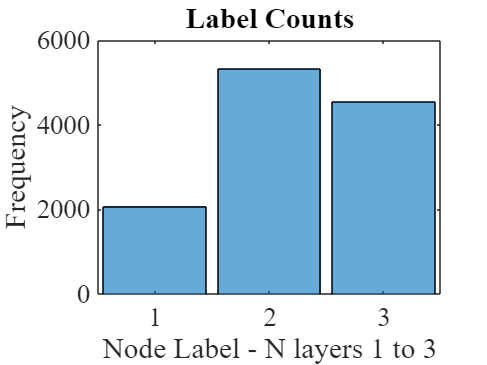

[symbol,count] = NRebarLayers(nodesNlay1to3);
figure(4)
histogram(categorical(symbol))
xlabel("Node Label - N layers 1 to 3")
ylabel("Frequency")
title("Label Counts")
hold on
set(gca, 'Fontname', 'Times New Roman','FontSize',20);

### **Partition of data**

numObservations = size(adjacency,3);
[idxTrain,idxValidation,idxTest] = trainingPartitions(numObservations,[0.7 0.15 0.15]);

% node adjacency data
adjacencyDataTrain = adjacency(:,:,idxTrain);
adjacencyDataValidation = adjacency(:,:,idxValidation);
adjacencyDataTest = adjacency(:,:,idxTest);

% feature data
DataXTrain1 = DataX1(:,:,idxTrain);
DataXValidation1 = DataX1(:,:,idxValidation);
DataXTest1 = DataX1(:,:,idxTest);

DataXTrain2 = DataX2(:,:,idxTrain);
DataXValidation2 = DataX2(:,:,idxValidation);
DataXTest2 = DataX2(:,:,idxTest);

DataXTrain3 = DataX3(:,:,idxTrain);
DataXValidation3 = DataX3(:,:,idxValidation);
DataXTest3 = DataX3(:,:,idxTest);

DataXTrain4 = DataX4(:,:,idxTrain);
DataXValidation4 = DataX4(:,:,idxValidation);
DataXTest4 = DataX4(:,:,idxTest);

DataXTrain5 = DataX5(:,:,idxTrain);
DataXValidation5 = DataX5(:,:,idxValidation);
DataXTest5 = DataX5(:,:,idxTest);

### **Target data**

diamDataTrain = nodesNlay1to3(idxTrain,:);
diamDataValidation = nodesNlay1to3(idxValidation,:);
diamDataTest = nodesNlay1to3(idxTest,:);

% Train partition
[ATrain,XTrain1,labelsTrain] = preprocessData(adjacencyDataTrain,DataXTrain1,diamDataTrain);
[~,XTrain2,~] = preprocessData(adjacencyDataTrain,DataXTrain2,diamDataTrain);
[~,XTrain3,~] = preprocessData(adjacencyDataTrain,DataXTrain3,diamDataTrain);
[~,XTrain4,~] = preprocessData(adjacencyDataTrain,DataXTrain4,diamDataTrain);
[~,XTrain5,~] = preprocessData(adjacencyDataTrain,DataXTrain5,diamDataTrain);

% Validation partition
[AValidation,XValidation1,labelsValidation] = preprocessData(adjacencyDataValidation,DataXValidation1,diamDataValidation);
[~,XValidation2,~] = preprocessData(adjacencyDataValidation,DataXValidation2,diamDataValidation);
[~,XValidation3,~] = preprocessData(adjacencyDataValidation,DataXValidation3,diamDataValidation);
[~,XValidation4,~] = preprocessData(adjacencyDataValidation,DataXValidation4,diamDataValidation);
[~,XValidation5,~] = preprocessData(adjacencyDataValidation,DataXValidation5,diamDataValidation);


Normalize the features using the mean and variance

muX1 = mean(XTrain1);
sigsqX1 = var(XTrain1,1);
XTrain1 = (XTrain1 - muX1)./sqrt(sigsqX1);
XValidation1 = (XValidation1 - muX1)./sqrt(sigsqX1);

muX2 = mean(XTrain2);
sigsqX2 = var(XTrain2,1);
XTrain2 = (XTrain2 - muX2)./sqrt(sigsqX2);
XValidation2 = (XValidation2 - muX2)./sqrt(sigsqX2);

muX3 = mean(XTrain3);
sigsqX3 = var(XTrain3,1);
XTrain3 = (XTrain3 - muX3)./sqrt(sigsqX3);
XValidation3 = (XValidation3 - muX3)./sqrt(sigsqX3);

muX4 = mean(XTrain4);
sigsqX4 = var(XTrain4,1);
XTrain4 = (XTrain4 - muX4)./sqrt(sigsqX4);
XValidation4 = (XValidation4 - muX4)./sqrt(sigsqX4);

muX5 = mean(XTrain5);
sigsqX5 = var(XTrain5,1);
XTrain5 = (XTrain5 - muX5)./sqrt(sigsqX5);
XValidation5 = (XValidation5 - muX5)./sqrt(sigsqX5);

XTrain=[XTrain1,XTrain2,XTrain3,XTrain4,XTrain5];
XValidation=[XValidation1,XValidation2,XValidation3,XValidation4,XValidation5];


## Define Model

Define the model. The model takes as input a feature matrix `X` and an adjacency matrix `A` and outputs categorical predictions.

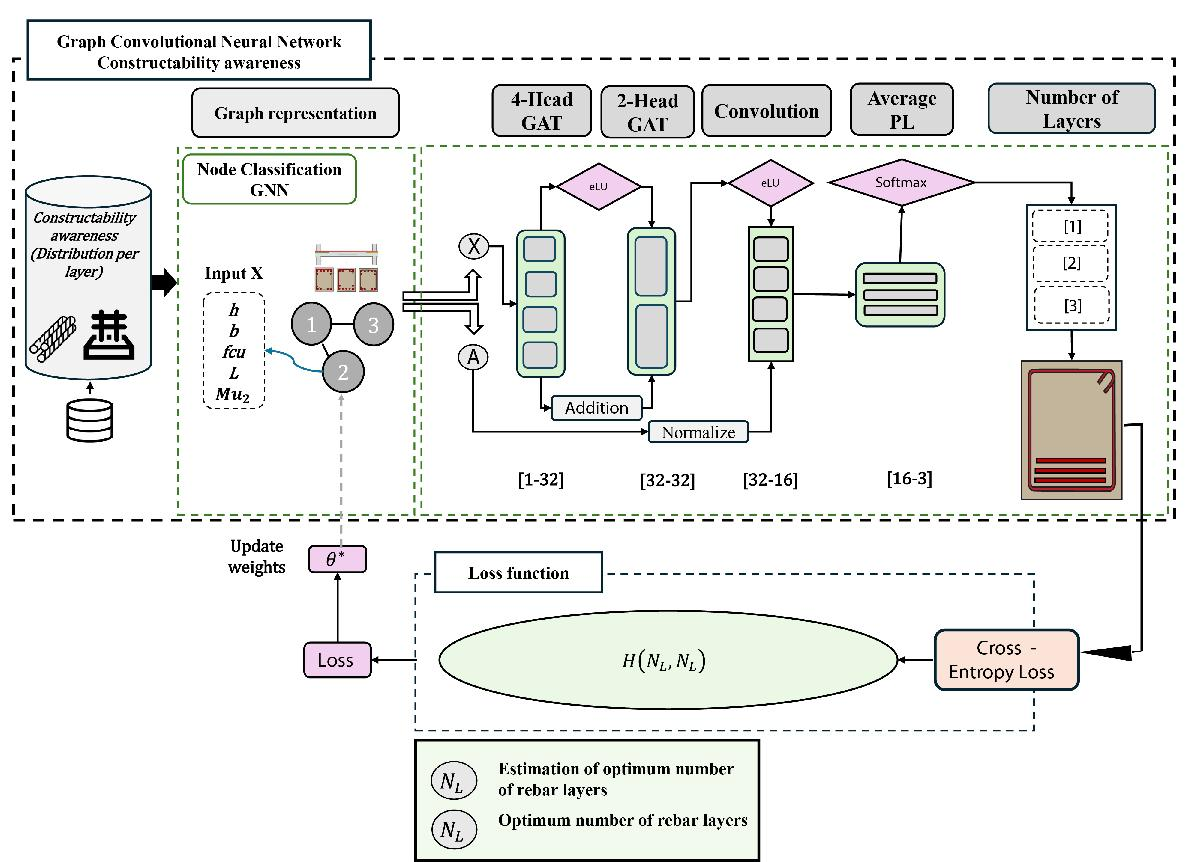

- The model uses a masked multihead self attention mechanism to aggregate features across the neighborhood of a node, that is, the set of nodes that are directly connected to the node. The mask, which is obtained from the adjacency matrix, is used to prevent *attention* between nodes that are not in the same neighborhood.

- The model uses ELU nonlinearity, after the first two attention operators, as the activation function.

- To aid convergence, the model uses a skip connection between the two attention operators.

- To make graph-level predictions using output node features, the model uses averaging to summarize the node features.

- Finally, the model computes independent class probabilities using a softmax operation.

### Initialize Model Parameters

Define the parameters for the each of the operations and include them in a structure.

Create a structure to contain the number of heads for the attention operations. 

Specify 4 heads for the first and 2 heads second attention operations. 

Use the format `parameters.operationName.parameterName`, where `parameters` is the structure, `operationName` is the name of the operation (for example, "attn1"), and `parameterName` is the name of the parameter (for example, "Weights"). 

Initialize the learnable weights using the `initializeGlorot` function, attached to this example as a supporting file. To access the function, open the example as a live script.

The attention operation uses two types of weights. Linear weights are used to transform the input features across different attention heads linearly. Attention weights are used to compute attention coefficients at each head. Specify the two weights in a structure with the fields `linearWeights` and `attentionWeights`. 

parameters = struct;
numHiddenFeatureMaps1 = 32;
numHiddenFeatureMaps2 = 16;
numInputFeatures = size(XTrain,2);

% Graph attention operation
numHeads=struct;

numHeads.attn1=4;
numHeads.attn2=2;

% First attention layer
sz = [numInputFeatures numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numInputFeatures;

parameters.attn1.Weights.linearWeights = initializeGlorot(sz,numOut,numIn,'double');
parameters.attn1.Weights.attentionWeights = initializeGlorot([numOut 2],1,2*numOut,'double');

% Second layer
sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numHiddenFeatureMaps1;

parameters.attn2.weights.linearWeights = initializeGlorot(sz,numOut,numIn);
parameters.attn2.weights.attentionWeights = initializeGlorot([numOut 2],1,2*numOut);

% Multiply operation
classes = categories(labelsTrain);
numClasses = numel(classes);

sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps2];
numOut = numHiddenFeatureMaps2;
numIn = numHiddenFeatureMaps1;

parameters.mult.Weights = initializeGlorot(sz,numOut,numIn,"double");


### Define Model Function

Create the function `model`, defined in the Model Function section of the example, which takes as input the model parameters, the input features and adjacency matrix, and the number of nodes per graph, and returns predictions for the labels.

### Define Model Loss Function

Create the function `modelLoss`, defined in the Model Loss Function section of the example, which takes as input the model parameters, a mini-batch of input features and corresponding adjacency matrix, the number of nodes per graph, and the corresponding encoded targets of the labels, and returns the loss, the gradients of the loss with respect to the learnable parameters, and the model predictions.

## Specify Training Options

Large mini-batches of training data for GATs can cause out-of-memory errors. If your hardware does not have enough memory, then reduce the mini-batch size. These parameters were optimized.

numEpochs = 160;
initialLearnRate = 0.02;
learnRateDecay=0.0;
nbatches=1;

validationFrequency = 10;

## Train Model

Train the model using a custom training loop.

Use `minibatchqueue` to process and manage mini-batches of training data. For each iteration and mini-batch:

- Discard partial mini-batches.

- Cast the data types of the output data to `double`. The adjacency data is returned as a sparse matrix, and `sparse` does not support `single`. By default, the `minibatchqueue` object casts the data type to `single`.

- Convert only the feature data to a `dlarray` object. By default, the `minibatchqueue` object converts all output data to `dlarray` objects.

if doTraining
    trailingAvg = [];
    trailingAvgSq = [];
    XTrain = dlarray(XTrain);
    XValidation = dlarray(XValidation);
    
    if canUseGPU
        XTrain = gpuArray(XTrain);
    end
    TTrain = onehotencode(labelsTrain,2,ClassNames=classes);
    TValidation = onehotencode(labelsValidation,2,ClassNames=classes);
    
    ngraphsTrain = size(XTrain, 1) / 3;
    ngraphsBatchTrain = fix(ngraphsTrain / nbatches);
    nnodesBatchTrain = ngraphsBatchTrain * 3;
    dsTrain = cell(nbatches, 2);
    for i = 1:nbatches
        i1 = (i-1)*nnodesBatchTrain + 1;
        i2 = i * nnodesBatchTrain;
        dsTrain{i,1} = XTrain(i1:i2, :);
        dsTrain{i,2} = TTrain(i1:i2, :);
    end
    
    monitor = trainingProgressMonitor( ...
        Metrics=["TrainingLoss","ValidationLoss"], ...
        Info="Epoch", ...
        XLabel="Epoch");
    
    groupSubPlot(monitor,"Loss",["TrainingLoss","ValidationLoss"])
    epoch = 0;
    iteration=0;
    while epoch < numEpochs && ~monitor.Stop
        epoch = epoch + 1;
        for j = 1:  nbatches
            iteration = iteration + 1;
            
            XTrain=dsTrain{j,1};
            TTrain=dsTrain{j,2};
            ATrain = sparse([]);

            for i=1:ngraphsBatchTrain
                A=adjacencyDataTrain(:,:,i);
                ATrain = blkdiag(ATrain,A);
            end
            % Evaluate the model loss and gradients.
            [loss(epoch),gradients] = dlfeval(@modelLoss2GAT1Conv,parameters,XTrain,ATrain,TTrain,numHeads);

            % Update the network parameters using the Adam optimizer.
            [parameters,trailingAvg,trailingAvgSq] = adamupdate(parameters,gradients, ...
                trailingAvg,trailingAvgSq,epoch,initialLearnRate);

            % Record the training loss and epoch.
            recordMetrics(monitor,epoch,TrainingLoss=loss(epoch));
            updateInfo(monitor,Epoch=(epoch+" of "+numEpochs));

            % Display the validation metrics.
            if epoch == 1 || mod(epoch,validationFrequency) == 0
                YValidation = model2GAT1Conv(parameters,XValidation,AValidation,numHeads);
                lossValidation(epoch) = crossentropy(YValidation,TValidation,DataFormat="BC");

                % Record the validation loss.
                recordMetrics(monitor,epoch,ValidationLoss=lossValidation(epoch));
            end
        end
        
        idx=randperm(nbatches);
        
        dsTrain=dsTrain(idx,:);
        updateInfo(monitor,Epoch=(epoch+" of "+numEpochs));
        monitor.Progress = 100*(epoch/numEpochs);
        initialLearnRate = initialLearnRate / (1 + learnRateDecay * epoch);
    end

    save('nLay_GNN_500.mat', 'parameters');
    save('nHead_nLay_GNN_500.mat', 'numHeads');
else

    paramNL=load('nLay_GNN_4000.mat');
    nheadsparamnNLGNN=load('nHead_nLay_GNN_4000.mat');
end

For each epoch, shuffle the data and loop over the mini-batches.

For each mini-batch:

- Evaluate the model loss and gradients using `dlfeval` and the `modelLoss` function.

- Update the network parameters using the `adamupdate` function.

- Update the training plot.

## Test Model

[ATest,XTest1,labelsTest] = preprocessData(adjacencyDataTest,DataXTest1,diamDataTest);
XTest1 = (XTest1 - muX1)./sqrt(sigsqX1);
XTest1 = dlarray(XTest1);

[~,XTest2,~] = preprocessData(adjacencyDataTest,DataXTest2,diamDataTest);
XTest2 = (XTest2 - muX2)./sqrt(sigsqX2);
XTest2 = dlarray(XTest2);

[~,XTest3,~] = preprocessData(adjacencyDataTest,DataXTest3,diamDataTest);
XTest3 = (XTest3 - muX3)./sqrt(sigsqX3);
XTest3 = dlarray(XTest3);

[~,XTest4,~] = preprocessData(adjacencyDataTest,DataXTest4,diamDataTest);
XTest4 = (XTest4 - muX4)./sqrt(sigsqX4);
XTest4 = dlarray(XTest4);

[~,XTest5,~] = preprocessData(adjacencyDataTest,DataXTest5,diamDataTest);
XTest5 = (XTest5 - muX5)./sqrt(sigsqX5);
XTest5 = dlarray(XTest5);

XTest=[XTest1,XTest2,XTest3,XTest4,XTest5];
if doTraining
    YTest = model2GAT1Conv(parameters,XTest,ATest,numHeads);
else
    YTest = model2GAT1Conv(paramNL.parameters,XTest,ATest,nheadsparamnNLGNN.numHeads);
end

YTest = onehotdecode(YTest,classes,2);

TTest = onehotencode(labelsTest,2,ClassNames=classes);

accuracy = mean(YTest == labelsTest)

accuracy = 0.5446

## **Confusion matrix**

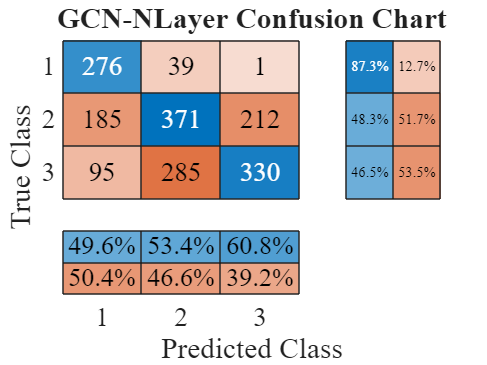

figure
cm = confusionchart(labelsTest,YTest, ...
    ColumnSummary="column-normalized", ...
    RowSummary="row-normalized");
title("GCN-NLayer Confusion Chart");
set(gca, 'Fontname', 'Times New Roman','FontSize',20);

## Model Function

The `model` function takes as inputs the model parameters `parameters`, the feature matrix `X`, the adjacency matrix `A`, the number of nodes per graph `numNodes`, and the number of heads `numHeads`, and returns the predictions and the attention scores.

The function:

- Computes the graph attention at each layer using the `graphAttention` function defined in the Attention Function section of the example.

- Uses ELU nonlinearity, using the `elu` function defined in the ELU Function section of the example as the activation function for the first two layers.

- Employs a residual connection in the hidden layer to aid convergence.

- Uses the `globalAveragePool` function, defined in the Global Average Pool Function section of the example, to perform the readout operation after the final layer.

- Uses the `sigmoid` function to compute the label predictions as independent class probabilities.


function Y = model2GAT1Conv(parameters,X,A,numHeads)

    weights1 = parameters.attn1.Weights;
    numHeadsAttention1 = numHeads.attn1;
    
    Z1 = X;
    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = elu(Z2);

    weights2 = parameters.attn2.weights;
    numHeadsAttention2 = numHeads.attn2;
    
    [Z3,~] = graphAttention(Z2,A,weights2,numHeadsAttention2,"cat");
    Z3  = elu(Z3) + Z2;
    
    ANorm = normalizeAdjacency(A);
    Z4 = single(full(ANorm)) * Z3 * double(parameters.mult.Weights);
    
    Z4 = graphPoolingLayer(Z4, 'mean', 3, 3);

    Y = softmax(Z4,DataFormat="BC");

end

## Model Loss Function

The `modelLoss` function takes as inputs the model parameters `parameters`, the feature matrix `X`, the adjacency matrix `adjacencyTrain`, the number of nodes per graph `numNodes`, the binary encoded labels `T`, and the number of heads `numHeads`, and returns the gradients of the loss with respect to the model parameters, the corresponding loss, and the model predictions.

function [loss,gradients] = modelLoss2GAT1Conv(parameters,X,A,T,numHeads)
    
    Y = model2GAT1Conv(parameters,X,A,numHeads);
    loss = crossentropy(Y,T,DataFormat="BC");
    gradients = dlgradient(loss, parameters);

end

## Attention Function

The `graphAttention` function computes node features using masked multihead self-attention.

Given input node features $Z_l$ of dimension $N \times F$, where $N$ is the number of nodes and $F$ is the number of input features, at layer $l$, the attention function computes the output node features $Z_{l+1}$ of dimension $N \times KF'$, where $KF'$ is the number of output features of the layer, as follows:

- Using $K$ independent heads, it computes linear transformations $H^k$, for $k = 1, ..., K$, of the input features using weight matrices $W_l^k$ of dimensions $F \times F'$. That is, $H^k = Z_lW_l^k$.

- It uses an attention mechanism to compute the scalar attention coefficients $\varepsilon^k_{nm} = a^k(h^k_n,h^k_m)$ for all node pairs $(n,m)$, where $h_n^k$ is a vector of dimension $1 \times F'$ corresponding to the *n*th row of matrix $H^k$. The attention coefficient $\varepsilon^k_{nm}$ represents the importance of node $m$ to node $n$ at head $k$. The attention mechanism $a$ can be a dot product operation of features $h_n$ and $h_m$, or a neural network. This example follows the approach in [1], where features $h_n$ and $h_m$ are concatenated and the attention mechanism is a single-layer neural network with weights array $\theta_l^k$, consisting of $2F'$ elements, that is shared across all nodes, followed by leaky-ReLU nonlinearity.

- To prevent attention between nodes that are not directly connected, the GAT implements masked attention by using the graph structure, defined by the adjacency matrix, to compute a mask such that the masked attention coefficients $\bar\varepsilon_{nm} = -\inf$ for all $m \notin \mathcal{N}_n$, where $\mathcal{N}_n$ is the neighborhood of node $n$, including $n$, and $\bar\varepsilon_{nm} = \varepsilon_{nm}$ for all $m \in \mathcal{N}_n$.

- Attention scores are computed by normalizing the masked attention coefficients using a softmax operation. That is, the attention score $\alpha_{nm}^k = \frac{\exp(\bar\varepsilon_{nm}^k)}{\sum_{j\in\mathcal{N}_n}\exp(\bar\varepsilon_{nj}^k)}$.

- The attention scores are then used to obtain the output features of the layer as a linear combination of transformations $H^k$. That is, given a $N \times N$matrix of attention scores $\mathbf{\alpha}^k$ computed at head $k$, output features $Z_{l+1}^k$ from attention head $k$ are obtained as $Z_{l+1}^k = \mathbf{\alpha}^kH^k$.

- The output features from each attention head are aggregated, either by concatenation, that is, $Z_{l+1} = [Z_{l+1}^1, ..., Z_{l+1}^K]$, or by averaging, that is $Z_{l+1}= \frac{1}{K}\sum_{k=1}^KZ_{l+1}^k$, to give the output features of the layer. 

The `graphAttention` function takes as inputs the feature matrix `inputFeatures`, adjacency matrix `adjacency`, learnable parameters `weights`, the number of heads `numHeads`, and aggregation method for the multiple attention heads `aggregation`, and computes and returns features using masked multihead self attention.

The function splits the learnable parameters into multiple heads, and for each attention head, it:

- Computes a linear transformation of the input features.

- Computes attention coefficients using linearly transformed features.

- Masks attention coefficients.

- Normalizes masked attention coefficients.

- Normalizes linearly transformed features using normalized masked attention coefficients.

Finally, it aggregates the output features of different attention heads.


function [outputFeatures,normAttentionCoeff] = graphAttention(inputFeatures,adjacency,weights,numHeads,aggregation)
    
    % Split weights with respect to the number of heads and reshape the matrix to a 3-D array
    szFeatureMaps = size(weights.linearWeights);
    numOutputFeatureMapsPerHead = szFeatureMaps(2)/numHeads;
    linearWeights = reshape(weights.linearWeights,[szFeatureMaps(1), numOutputFeatureMapsPerHead, numHeads]);
    attentionWeights = reshape(weights.attentionWeights,[numOutputFeatureMapsPerHead, 2, numHeads]);
    
    % Compute linear transformations of input features
    value = pagemtimes(inputFeatures,linearWeights);
    
    % Compute attention coefficients
    query = pagemtimes(value, attentionWeights(:, 1, :));
    key = pagemtimes(value, attentionWeights(:, 2, :));
    
    attentionCoefficients = query + permute(key,[2, 1, 3]);
    attentionCoefficients = leakyrelu(attentionCoefficients,0.2);
    
    % Compute masked attention coefficients
    mask = -10e9 * (1 - adjacency);
    attentionCoefficients = attentionCoefficients + mask;
    
    % Compute normalized masked attention coefficients
    normAttentionCoeff = softmax(attentionCoefficients,DataFormat = "BCU");
    
    % Normalize features using normalized masked attention coefficients
    headOutputFeatures = pagemtimes(normAttentionCoeff,value);
    
    % Aggregate features from multiple heads
    if strcmp(aggregation, "cat")
        outputFeatures = headOutputFeatures(:,:);
    else
        outputFeatures =  mean(headOutputFeatures,3);
    end

end

function pooledFeatures = graphPoolingLayer(nodeFeatures, poolType, outputDim, numNodes)

    % Input validation
    if ~ischar(poolType) || ~ismember(lower(poolType), {'mean', 'max', 'sum'})
        error('poolType must be ''mean'', ''max'', or ''sum''.');
    end
    numFeatures = size(nodeFeatures, 2); % Number of input features per node, e.g., 5
    nGraphs = size(nodeFeatures, 1)/numNodes;
    % If outputDim equals input feature dimension, apply pooling without coarsening
    if outputDim == numFeatures
        switch lower(poolType)
            case 'mean'
                for i=1:nGraphs
                    i1=(i-1)*numNodes+1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = mean(nodeFeatures(i1:i2,:), 2) * ones(1, outputDim,'like',nodeFeatures);
                end
            case 'max'
                for i=1:nGraphs
                    i1=(i-1)*numNodes +1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = max(nodeFeatures(i1:i2,:), [], 2) * ones(1, outputDim,'like',nodeFeatures);
                end
            case 'sum'
                for i=1:nGraphs
                    i1=(i-1)*numNodes +1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = sum(nodeFeatures(i1:i2,:), 2) * ones(1, outputDim,'like',nodeFeatures);
                end
        end
        return;
    end

    % Determine grouping of features for pooling
    if outputDim < numFeatures
        % Group features into approximately equal-sized subsets
        groupSize = ceil(numFeatures / outputDim);
        pooledFeatures = dlarray(zeros(numNodes*nGraphs, outputDim));
        
        for i = 1:outputDim
            startIdx = (i-1) * groupSize + 1;
            endIdx = min(i * groupSize, numFeatures);
            if startIdx > numFeatures
                break; % No more features to process
            end
            featureSubset = nodeFeatures(:, startIdx:endIdx);
            
            % Apply pooling operation
            switch lower(poolType)
                case 'mean'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes+1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = mean(featureSubset(i1:i2,:), 2);
                    end
                case 'max'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes +1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = max(featureSubset(i1:i2,:), [], 2);
                    end
                case 'sum'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes +1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = sum(featureSubset(i1:i2,:), 2);
                    end
            end
        end
    else
        % If outputDim > numFeatures, pad with zeros or repeat features
        pooledFeatures = zeros(numNodes*nGraphs, outputDim);
        switch lower(poolType)
            case 'mean'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = mean(nodeFeatures(i1:i2,:), 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
            case 'max'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = max(nodeFeatures(i1:i2,:), [], 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
            case 'sum'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = sum(nodeFeatures(i1:i2,:), 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
        end
        % Fill output dimensions with base features and pad with zeros if necessary
        pooledFeatures(:, 1:numFeatures) = baseFeatures;
    end
end

function [adjacency,features] = preprocessPredictors(adjacencyData,coulombData)

    adjacency = sparse([]);
    features = [];
    
    for i = 1:size(adjacencyData, 3)
        % Extract unpadded data.
        numNodes = find(any(adjacencyData(:,:,i)),1,"last");
    
        A = adjacencyData(1:numNodes,1:numNodes,i);
        X = coulombData(1:numNodes,1:numNodes,i);
    
        % Extract feature vector from diagonal of Coulomb matrix.
        X = diag(X);
    
        % Append extracted data.
        adjacency = blkdiag(adjacency,A);
        features = [features; X];
    end

end

function [adjacency,features,labels] = preprocessData(adjacencyData,coulombData,atomData)

    [adjacency, features] = preprocessPredictors(adjacencyData,coulombData);
    labels = [];
    
    % Convert labels to categorical.
    for i = 1:size(adjacencyData,3)
        % Extract and append unpadded data.
        T = nonzeros(atomData(i,:));
        labels = [labels; T];
    end
    
    labels2 = nonzeros(atomData);
    %labels2 = atomData;
    assert(isequal(labels2,labels2))
    
    diamSizeNodes = unique(labels);

    diamSizes =  NRebarLayers(diamSizeNodes);
    labels = categorical(labels, diamSizeNodes, diamSizes);

end


function [symbol,count] = NRebarLayers(atomicNum)
% ATOMICSYMBOL Convert atomic number to symbol
%   symbol = atomicSymbol(atomicNum) returns the atomic symbol of the
%   specified atomic number.
%
%   [symbol,count] = atomicSymbol(atomicNum) also returns the count for
%   each symbol.
%

numSymbols = numel(atomicNum);

symbol = strings(numSymbols, 1);
count = strings(numSymbols,1);


Count1 = 0;
Count2 = 0;
Count3 = 0;
for i = 1:numSymbols
    switch atomicNum(i)
        case 1
            symbol(i) = 1;
            Count1 = Count1 + 1;
            count(i) = "1" + Count1;
        case 2
            symbol(i) = 2;
            Count2 = Count2 + 1;
            count(i) = "2" + Count2;
        case 3
            symbol(i) = 3;
            Count3 = Count3 + 1;
            count(i) = "3" + Count3;
    end
end

end

function weights = initializeGlorot(sz,numOut,numIn,className)

    arguments
        sz
        numOut
        numIn
        className = 'single'
    end
    
    Z = 2*rand(sz,className) - 1;
    bound = sqrt(6 / (numIn + numOut));
    
    weights = bound * Z;
    weights = dlarray(weights);

end

function parameter = initializeZeros(sz,className)
    
    arguments
        sz
        className = 'single'
    end
    
    parameter = zeros(sz,className);
    parameter = dlarray(parameter);

end


## ELU Function

The `elu` function implements the ELU activation function defined as


$$f\left(x\right)=\left\lbrace \begin{array}{ll}
x, & x\ge 0\\
\alpha \left(\exp \left(x\right)-1\right), & x<0
\end{array}\right.$$


The function uses $\alpha =1\ldotp$

function y = elu(x)

y = max(0, x) + (exp(min(0, x)) -1);

end


function ANorm = normalizeAdjacency(A)

% Add self connections to adjacency matrix.
A = A + speye(size(A));

% Compute inverse square root of degree.
degree = sum(A, 2);
degreeInvSqrt = sparse(sqrt(1./degree));

% Normalize adjacency matrix.
ANorm = diag(degreeInvSqrt) * A * diag(degreeInvSqrt);

end

function varargout = trainingPartitions(numObservations,splits)
%TRAININGPARTITONS Random indices for splitting training data
%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
%   random vectors of indices to help split a data set with the specified
%   number of observations, where SPLITS is a vector of length N of
%   partition sizes that sum to one.
%
%   % Example: Get indices for 50%-50% training-test split of 500
%   % observations.
%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
%
%   % Example: Get indices for 80%-10%-10% training, validation, test split
%   % of 500 observations. 
%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])
%{
arguments
    numObservations (1,1) {mustBePositive}
    splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
end
%}
numPartitions = numel(splits);
varargout = cell(1,numPartitions);

idx = randperm(numObservations);

idxEnd = 0;

for i = 1:numPartitions-1
    idxStart = idxEnd + 1;
    idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

    varargout{i} = idx(idxStart:idxEnd);
end

% Last partition.
varargout{end} = idx(idxEnd+1:end);

end

function mustSumToOne(v)
    % Validate that value sums to one.
    
    if sum(v,"all") ~= 1
        error("Value must sum to one.")
    end

end

## References